## Calcolo Autovalori e Autovettori

Data una matrice A, in matlab i suoi autovalori si calcolano con il comando eigs(A).

Se si richiama eigs con 2 valori di output si ottengono la matrice diagonale degli autovalori e la matrice degli autovettori:

 [V,D] = eigs(A) dove V è la matrice degli autovettori e D è una matrice avente nella diagonale gli autovalori di A.

Al vettore i-esimo di V è associato l'autovettore i-esimo di D (stesso indice di colonna).

Lo spettro della matrice A si può trovare estraendo la diagonale di D con il comando diag(D).

per trovare il raggio spettrale di A ci sono diversi approcci:

- prendere il valore max della diagonale di D

- ordinare il vettore degli autovalori e prendere il maggiore

- usare il comando eigs con l'opzione "largestabs"

A = rand(10);
[V,D] = eig(A)

V =    0.3654 + 0.0000i   0.1748 + 0.0000i   0.2504 + 0.3083i   0.2504 - 0.3083i   0.2727 + 0.0000i  -0.0459 - 0.2703i  -0.0459 + 0.2703i  -0.4694 + 0.0000i   0.3405 + 0.0745i   0.3405 - 0.0745i
   0.4247 + 0.0000i  -0.6090 + 0.0000i  -0.3168 - 0.0321i  -0.3168 + 0.0321i   0.0141 + 0.0000i  -0.2301 + 0.3680i  -0.2301 - 0.3680i   0.0663 + 0.0000i  -0.3364 - 0.0485i  -0.3364 + 0.0485i
   0.2768 + 0.0000i  -0.2143 + 0.0000i   0.1438 - 0.1986i   0.1438 + 0.1986i  -0.1106 + 0.0000i   0.4021 + 0.0517i   0.4021 - 0.0517i  -0.5193 + 0.0000i  -0.0883 + 0.0264i  -0.0883 - 0.0264i
   0.2796 + 0.0000i   0.4770 + 0.0000i  -0.2506 - 0.1742i  -0.2506 + 0.1742i  -0.0618 + 0.0000i  -0.0367 + 0.2304i  -0.0367 - 0.2304i   0.0342 + 0.0000i  -0.1775 + 0.2125i  -0.1775 - 0.2125i
   0.2328 + 0.0000i   0.1047 + 0.0000i   0.2271 - 0.1609i   0.2271 + 0.1609i  -0.6286 + 0.0000i  -0.2009 - 0.3064i  -0.2009 + 0.3064i   0.1859 + 0.0000i   0.3155 - 0.1067i   0.3155 + 0.1067i
   0.3818 + 0.0000i   0.4721 + 0.0000i   

D =    4.8786 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.0694 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.6940 + 0.3937i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.6940 - 0.3937i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.6141 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   


spettro = diag(D)

spettro =    4.8786 + 0.0000i
   1.0694 + 0.0000i
  -0.6940 + 0.3937i
  -0.6940 - 0.3937i
  -0.6141 + 0.0000i
   0.3545 + 0.5103i
   0.3545 - 0.5103i
   0.3395 + 0.0000i
  -0.0153 + 0.3110i
  -0.0153 - 0.3110i



rho1 = max(abs(spettro))

rho1 = 4.8786

tmp = sort(abs(spettro),'descend')

tmp =     4.8786
    1.0694
    0.7979
    0.7979
    0.6214
    0.6214
    0.6141
    0.3395
    0.3114
    0.3114


rho2 = tmp(1)

rho2 = 4.8786

rho3 = abs(eigs(A,1,"largestabs"))

rho3 = 4.8786

## Risoluzione di un sistema lineare

In matlab un sistema lineare nella forma Ax=b si risolve tramite l'operatore \, che corrisponde a calcolare inv(A)*b.

l'utilizzo di \ è consigliato perchè va ad usare l'algoritmo ottimale in base alla struttura della matrice.

In caso la matrice non ha una struttura particolare utilizza Gauss.

Attenzione alle dimensioni della matrice e del vettore.

A = rand(10)

A =     0.8729    0.3287    0.3717    0.8986    0.1751    0.2971    0.8593    0.5181    0.7472    0.9766
    0.8057    0.6496    0.1919    0.9102    0.5884    0.0612    0.7732    0.3675    0.6110    0.9602
    0.8512    0.7866    0.9971    0.9942    0.3978    0.3448    0.2321    0.8412    0.9944    0.3944
    0.3503    0.0578    0.6462    0.2996    0.9199    0.1576    0.2675    0.3637    0.2740    0.5578
    0.1638    0.9092    0.2501    0.2021    0.2953    0.5684    0.1673    0.5011    0.8383    0.6152
    0.8624    0.8218    0.3843    0.5162    0.6918    0.4376    0.1159    0.1348    0.9625    0.4571
    0.6518    0.7939    0.3896    0.7568    0.8034    0.3295    0.5183    0.1657    0.7151    0.3526
    0.8500    0.5049    0.2204    0.4596    0.9098    0.0397    0.8799    0.9854    0.0987    0.7662
    0.3257    0.6519    0.6214    0.9464    0.4617    0.2856    0.3928    0.6352    0.5971    0.2697
    0.6481    0.7652    0.5217    0.2547    0.4471    0.2814    0.1028    0.2022    0.6

A = A*A';
b = rand(10,1)

b =     0.2430
    0.3217
    0.2823
    0.7771
    0.8063
    0.9335
    0.0613
    0.2001
    0.8848
    0.2973



if det(A) <= 1e-14
    error("La matrice è singolare")
end
if size(A,1) ~= size(b,1)
    error ("A e b devono avere lo stesso numero di righe")
end
if size(b,2) ~= 1
    error ("b deve essere un vettore")
end

x = A\b

x =    67.1647
   -4.0413
 -252.0567
    7.5305
  -74.1814
  171.8014
 -297.3955
   -3.0815
  322.0224
  176.5384


## Metodo di Gauss

il metodo di riduzione di Gauss permette, dato un sistema lineare generico, di ottenere un sistema triangolare superiore equivalente, il quale può essere risolto tramite l'algoritmo di sostituzione.

### pseudocodice

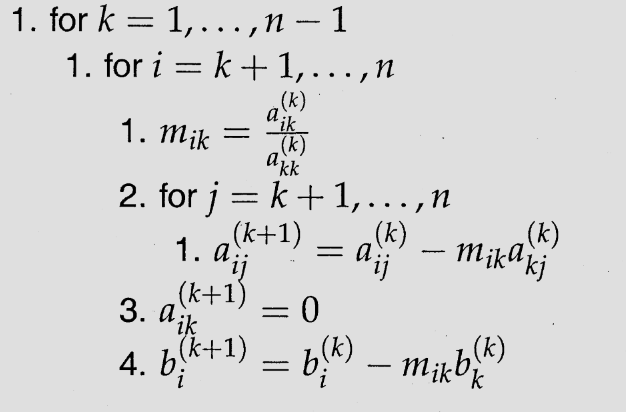

### implementazione

n = size(A,1);    
for k = 1 : n-1
    for i = k+1 : n
        m = A(i,k)/A(k,k);
        % for j = k+1:n
        %     A(i,j) = A(i,j) - m * A(k,j);
        % end
        A(i,:) = A(i,:) - m * A(k,:);
        A(i,k) = 0;
        b(i) = b(i) - m*b(k);
    end
end
    
disp(A)

    4.4534    4.1762    4.2012    2.2098    2.5675    3.2157    3.3031    3.6626    3.1218    2.1901
         0    0.3981    0.0835    0.2385    0.1718    0.3566    0.4367    0.4150    0.1890    0.2420
         0         0    1.5284    0.4319    0.6968    0.8724    0.6556    0.0644    0.9736    0.9374
         0         0         0    0.7329   -0.0808    0.0007    0.0490    0.4141    0.0191   -0.0076
         0         0         0         0    0.8464    0.3114    0.1033   -0.0418    0.0186    0.1957
         0         0         0         0         0    0.4163    0.1980   -0.2415   -0.1687    0.2344
         0         0         0         0         0         0    0.1448   -0.0147    0.1202    0.0213
         0         0         0         0         0         0         0    0.5834   -0.0547    0.1088
         0         0         0         0         0         0         0         0    0.0219   -0.0330
         0         0         0         0         0         0         0         0         0 

disp(b)

    0.2430
    0.0938
    0.0334
    0.5909
    0.6756
    0.4058
   -0.5511
   -0.2199
    1.2198
    1.6833



### test

Andiamo a creare un test che calcola l'errore relativo per la risoluzione di un sistema lineare dopo il metodo di riduzione di Gauss.

for n = 10: 10 : 100
    A = rand(n);
    A = A*A';
    b = rand(n,1);
    x = A\b;

    [C,d] = gauss(A,b);

    x_g = C\d;

    err = norm(x-x_g) / norm(x);
    fprintf("\nL'errore relativo con n = %d è %d",n,err);
end


L'errore relativo con n = 10 è 9.349350e-15
L'errore relativo con n = 20 è 1.293891e-13
L'errore relativo con n = 30 è 5.165390e-14
L'errore relativo con n = 40 è 4.073499e-13
L'errore relativo con n = 50 è 6.774245e-13
L'errore relativo con n = 60 è 2.727738e-12
L'errore relativo con n = 70 è 9.126271e-11
L'errore relativo con n = 80 è 2.064903e-13
L'errore relativo con n = 90 è 1.138810e-11
L'errore relativo con n = 100 è 2.318268e-11